モノポール１０点送信と10点一斉送信のRFデータにどれほどの差があるのかを，均質媒質でのシミュレーションを用いて検証する．

ch:10, 20, ..., 100

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_23_validate_plnwv_monopole\NoObject.mat')
load('rfdata')
rfdata_simul = rfdata;
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_05_no_object\NoObject')
load('rfdata')
rfdata_mono = rfdata;
rfdata_simul=rfdata_simul(1:length(rfdata_mono),:);
rfdata_assem_mono = zeros(size(rfdata_simul));

for ii = 10:10:100
    rfdata_assem_mono = rfdata_assem_mono + rfdata_mono(:,:,ii);
end

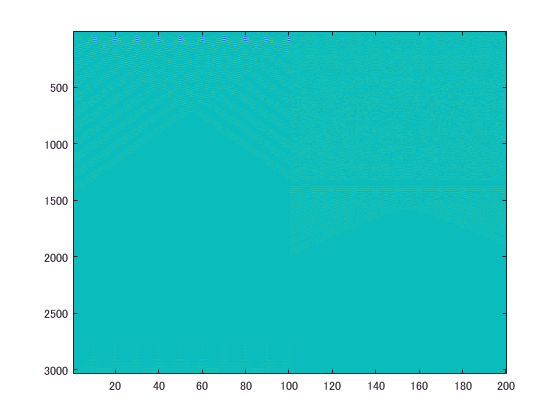

figure;
imagesc(rfdata_assem_mono - rfdata_simul)
caxis([-0.1 0.1])

r = sqrt(sum(sum((rfdata_assem_mono - rfdata_simul).^2)))/numel(rfdata_assem_mono - rfdata_simul)

r = 2.5746e-06

ほとんど誤差はなく，ホイヘンスの原理を適用して平面波を合成してもよさそう．

しかし，本当は計算時間を短くするために，手法を簡略化するために平面波送信をしたい．

現時点では変数source.pを全チャンネル一斉送信するように指定しているのだが，一部チャンネルからしか送信されていないという結果になっている．